# Lab 3: OFDM Modulation

Kristtiya Guerra and Utsav Gupta

clc; clear all; close all;

#### Parameters

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16;    % Sets of Training Data 
N_XData = 84;       % Sets of True Data 
Bits_per_set = 64;  % Bits per set of data
size_training_data = Bits_per_set*N_Training;       % Size of Training Data - 16 sets of 64 bits: 1024
size_X = Bits_per_set*N_XData;                      % Size of data - 84 sets of 64 bits: 5376 bits

#### Generating Random Data to Transmit

Create Data and Training Data

range = [-1 1]; % List of wanted values: 
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

#### IDFT - Takes inverse discrete fourier tranform of data

Add Cyclic Prefix after each ifft

%IFFT of each individual set of 64
%Add prefix 
Len_CP = 16;
n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data
tx_data = zeros(8000,1);


for x_time = 1:1:5
    Data_x_n = message(1 + 64*(x_time-1):x_time*64); %Extracts data set n_data - 64 bits
    Data_X_n = ifft(Data_x_n);  %Obtains the ifft of the data: Frequency to Time- 64 bits
    test_recovery = fft(Data_X_n);
    cyclic_prefix = Data_X_n(49:end); % Obtains the last 16 bits of the data
    recoverprefix = fft(cyclic_prefix);
    Prefix_w_data = [cyclic_prefix ; Data_X_n];%Concatonate the cyclic prefix to the data set - 80 bits
    test_recovery1 = fft(Prefix_w_data); %Time to frequency
    test_woutpre = fft(Prefix_w_data(17:end));
    tx_data(1+80*(x_time-1):80*(x_time)) = Prefix_w_data;%Append data into the tx_data vector
end


#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel(tx_data);

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index); %Should be 9

%Remove Extra Data
rx_data = rx_data(shift1_train:end); %Should be 8000 bits

Estimate Channel: Estimating channel for each set of 64 bits using the Training Data

%Obtain Training Data
Size_PC = 16;
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_set; %1280 Bits
Training_data_xm= rx_data(1:Size_Training_PC);
Cleaned_Training_Data = zeros(N_Training*Bits_per_set,1);

%removing cyclic prefix
for V = 1:1:16
    Set = Training_data_xm(1 + 80*(V-1):80*V);
    remove_prefix = Set(17:end);
    dat = (fftshift(fft(remove_prefix))); %Move data to the frequency domain
    Cleaned_Training_Data(1+64*(V-1):64*V) = dat;
end

H_est = zeros(64,1); %Create empty vector for Channel Estimate
Original_Training= message(1:size_training_data); %Obtain original training data
Pre_H_est = zeros(N_Training*Bits_per_set,1);

for Z = 1:1:N_Training*Bits_per_set
    Channel_estimate = Cleaned_Training_Data(Z)/Original_Training(Z);
    Pre_H_est(Z) = Channel_estimate;
end

for G = 1:1:64
    %Channel_estimate = Cleaned_Training_Data./Original_Training; % Estimate the channel
    h_est_obtain = Pre_H_est(G:64:end);
    H_est(G) = mean(h_est_obtain);
end
H_est

H_est =   -0.0531 - 0.0017i
  -0.0200 - 0.0093i
  -0.0307 - 0.0196i
   0.1258 + 0.0726i
   0.0544 + 0.0226i
  -0.0693 - 0.0136i
  -0.0721 - 0.0030i
  -0.2269 + 0.0349i
  -0.0757 + 0.0236i
  -0.0702 + 0.0349i


Alpha = Cleaned_Training_Data(1:64);
result = Alpha./H_est

result =    5.5565 - 0.2488i
  17.6185 + 0.7952i
 -15.7489 - 0.3303i
   5.3454 - 0.0788i
 -16.1129 + 0.5364i
 -15.3805 - 0.0187i
 -16.3894 + 0.3972i
  -5.3965 - 0.0102i
 -15.9513 + 0.1871i
 -16.0708 - 0.1224i


Decode

Y_m = zeros(length(message),1);

for V = 1:1:n_data
    Set = rx_data(1 + 80*(V-1):80*V); %Extract n_data set of 80 bits - 80 bits
    remove_prefix = Set(17:end); %Remove Cyclic prefix and produce true data - 64 bits
    Y = fftshift(fft(remove_prefix)); %Move data to frequency domain - Move data to the frequency domain
    X_est=Y./H_est;
    Y_m(1 + 64*(V-1):64*V) = X_est;
end

Plot X_est

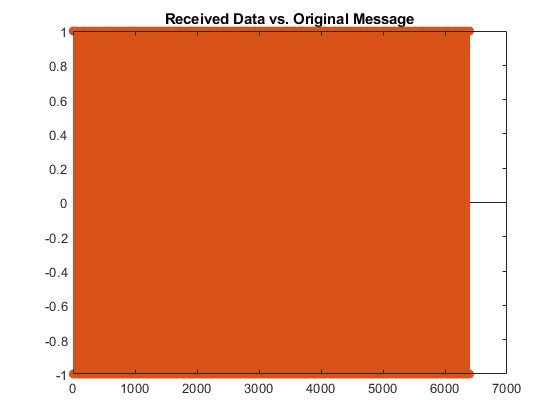

Norm_ret = real(Y_m) ./ abs(real(Y_m));

figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Error = abs(sum(diff)/(length(diff))) *100

Error = 48.3906

sps =2

sps = 2

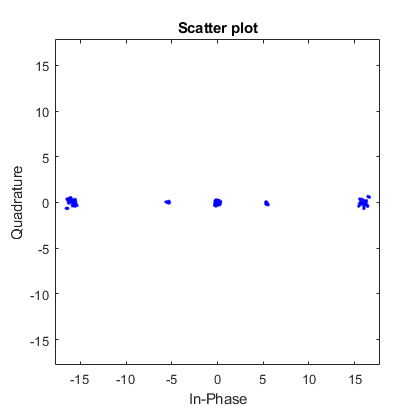

constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',sps, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);
scatterplot(Y_m,2)

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end


Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);